# Transfer Functions

Transfer functions are input to output representations of dynamic systems. One advantage of working in the Laplace domain (versus the time domain) is that differential equations become algebraic equations. These algebraic equations can be rearranged and transformed back into the time domain to obtain a solution or further combined with other transfer functions to create more complicated systems. The first step in creating a transfer function is to convert each term of a differential equation with a Laplace transform as shown in the [**table of Laplace transforms**](https://apmonitor.com/pdc/index.php/Main/LaplaceTransforms). A transfer function, $G(s)$, relates an input, $U(s)$, to an output, $Y(s)$.


$$G(s)=\frac{Y(s)}{U(s)}$$


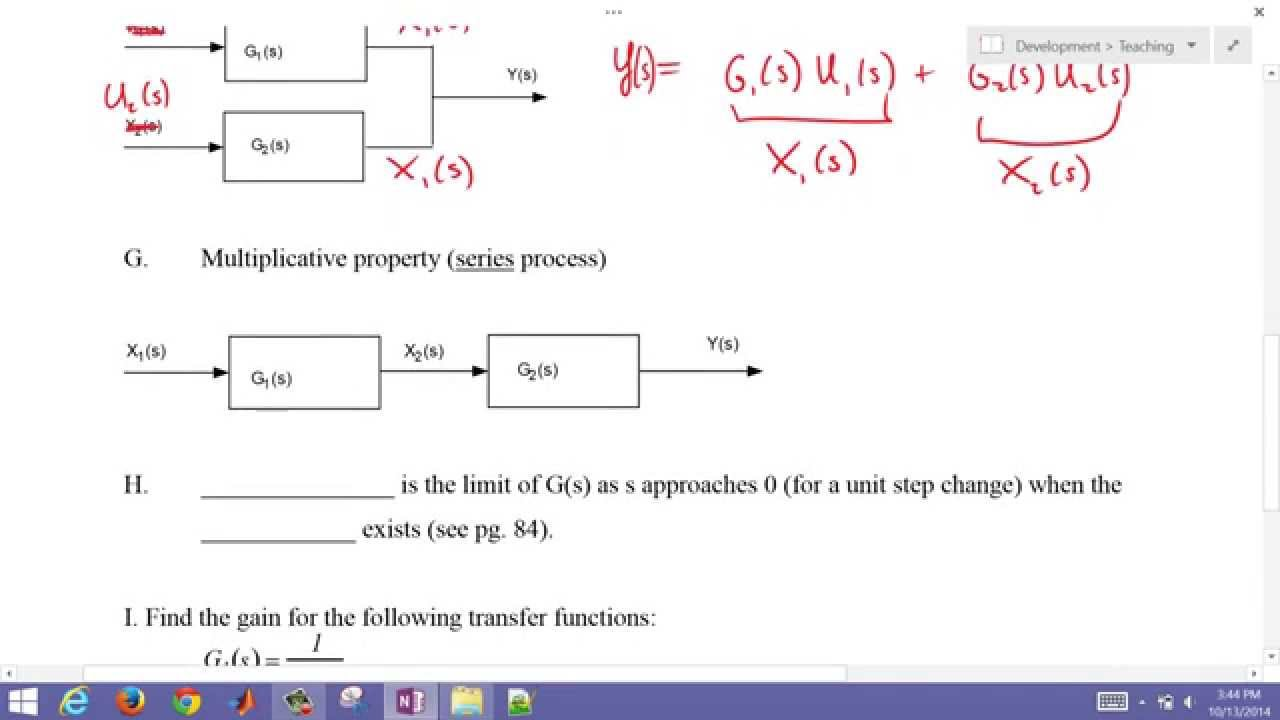

### [View Lecture](https://www.youtube.com/watch?v=8Bd9V4M93tY)

## First-order Transfer Function

A first-order linear differential equation is shown as a function of time.


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


The first step is to apply the [**Laplace transform**](https://apmonitor.com/pdc/index.php/Main/LaplaceTransforms) to each of the terms in the differential equation.


$$\mathcal{L}\left(\tau_p \frac{dy(t)}{dt}\right) = \mathcal{L}\left(-y(t)\right) + \mathcal{L}\left(K_p u\left(t-\theta_p\right)\right)$$


Because the Laplace transform is a linear operator, each term can be transformed separately. With a zero initial condition the value of $y$ is zero at the initial time or$y(0)=0$.


$$\mathcal{L}\left(\tau_p \frac{dy(t)}{dt}\right) = \tau_p \left(s \, Y(s) - y(0)\right) = \tau_p s \, Y(s)$$



$$\mathcal{L}\left(-y(t)\right) = -Y(s)$$



$$\mathcal{L}\left(K_p u\left(t-\theta_p\right)\right) = K_p \, U(s) \, e^{-\theta_p s}$$


Putting these terms together gives the first-order differential equation in the Laplace domain.


$$\tau_p s \, Y(s) = -Y(s) + K_p \, U(s) \, e^{-\theta_p s}$$


For the first-order linear system, the transfer function is created by isolating terms with $Y(s)$ on the left side of the equation and the term with $U(s)$ on the right side of the equation.


$$\tau_p s \, Y(s) + Y(s) = K_p \, U(s) \, e^{-\theta_p s}$$


Factoring out the $Y(s)$ and dividing through gives the final transfer function.


$$G(s) = \frac{Y(s)}{U(s)} = \frac{K_p e^{-\theta_p s}}{\tau_p s + 1}$$


## Transfer Function Gain

The Final Value Theorem (FVT) gives the steady state gain $K_p$ of a transfer function $G(s)$ by taking the limit as $s \rightarrow 0$


$$K_p = \lim_{s \to 0}G(s)$$


This is related to the final value theorem by considering the output response $Y(s)$ when the input is a unit step $U(s)=\frac{1}{s}$.


$$K_p = \frac{\Delta y}{\Delta u} =  \lim_{s \to 0}G(s) = \lim_{s \to 0}\frac{Y(s)}{U(s)} = \lim_{s \to 0}\frac{Y(s)}{\frac{1}{s}}$$



$$\frac{\Delta y}{\Delta u} = \lim_{s \to 0}\frac{Y(s)}{\frac{1}{s}}$$


In deviation variable form, the initial condition for $u$ and $y$ is zero.


$$\frac{y_\infty-0}{1-0} = y_\infty = \lim_{s \to 0}\frac{Y(s)}{\frac{1}{s}} = \lim_{s \to 0}s Y(s)$$


The FVT also determines the final signal value $y_\infty$ for a stable system with output $Y(s)$. The Laplace variable $s$ is multiplied by the signal $Y(s)$ before the limit is taken, unlike when calculating the gain.


$$y_\infty = \lim_{s \to 0} s \, Y(s)$$


The FVT may give misleading results if applied to an unstable system. It is only applicable to stable systems. There is additional information on how to [**determine if a system is stable**](https://apmonitor.com/pdc/index.php/Main/StabilityAnalysis).

## PID Equation in Laplace Domain

The PID equation is a block in an overall control loop diagram.


$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\int_0^t e(t)dt - K_c \tau_D \frac{d(PV)}{dt}$$


The PID equation can be converted to a transfer function by performing a Laplace transform on each of the elements. The controller output $u(t)$ is combined with the $u_{\text{bias}}$ to create a deviation variable $u'(t)=u(t)-u_{\text{bias}}$.


$$U(s) = K_c \, E(s) + \frac{K_c}{\tau_I \, s}E(s) - K_c \, \tau_D PV(s)$$


If $\tau_D=0$ for a PI controller, the transfer function for the controller is simplified.


$$G_c(s) = \frac{U(s)}{E(s)} = K_c + \frac{K_c}{\tau_I \, s} = K_c \, \frac{\left(\tau_I s + 1\right)}{\tau_I s}$$


## Combining Transfer Functions

The additive property is used for transfer functions in parallel. The input signal $X_1(s)$ becomes $Y_1(s)$ when it is transformed by $G_1(s)$. Likewise, $X_2(s)$ becomes$Y_2(s)$ when it is transformed by $G_2(s)$. The two signals $Y_1(s)$ and $Y_2(s)$ are added to create the final output signal $Y(s) = Y_1(s)+Y_2(s)$. This gives a final output expression of $Y(s)=G_1(s)X_1(s)+G_2(s)X_2(s)$.

 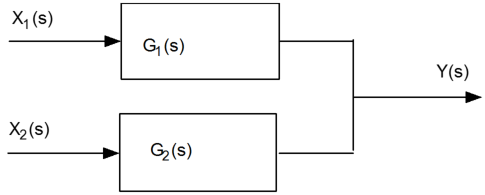

The multiplicative property is used for transfer functions in series. The input signal $X_1(s)$ becomes $X_2(s)$ when it is transformed by $G_1(s)$. The intermediate signal $X_2(s)$ becomes the input for the second transfer function $X_2(s)$ to produce $Y(s)$. The final output signal is $Y(s)=G_2(s) X_2(s) = G_1(s) G_2(s) X_1(s)$.

## Transfer Functions with MATLAB

MATLAB syms can create symbolic solutions to many mathematical problems including Laplace transforms. A symbolic and numeric solution is created with the following example problem.

Compute the analytic and numeric system response to an input that includes a step and ramp function.

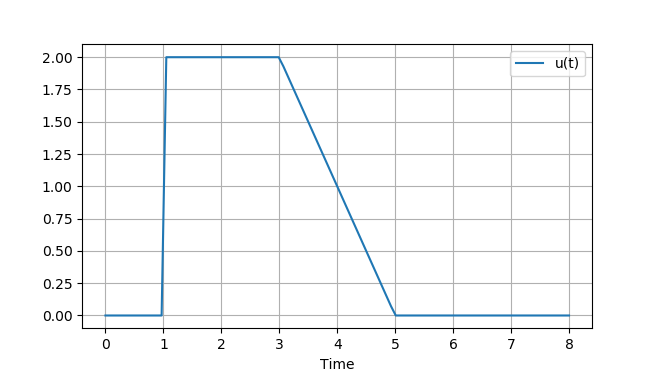

The system transfer function is a stable system with two poles (denominator roots) and one zero (numerator root):


$$G(s) = \frac{5(s+1)}{(s+3)^2$$


### Symbolic Solution

Initialize symbolic variables

syms s t x y z;

Define inputs in laplace form

% First step up starts at 1 sec
U1 = 2/s*exp(-s)

$$U1 = \frac{2\,{\mathrm{e}}^{-s}}{s}$$

% Ramp down begins at 3 sec
U2 = -1/s^2 * exp(-3*s)

$$U2 = -\frac{{\mathrm{e}}^{-3\,s}}{s^{2}}$$

% Ramp down ends at 5 sec
U3 = 1/s^2 * exp(-5*s)

$$U3 = \frac{{\mathrm{e}}^{-5\,s}}{s^{2}}$$

Define Transfer function

G = 5*(s+1)/(s+3)^2

$$G = \frac{5\,s+5}{{\left(s+3\right)}^{2}}$$

Calculate Responses

Y1 = G * U1

$$Y1 = \frac{2\,{\mathrm{e}}^{-s}\,\left(5\,s+5\right)}{s\,{\left(s+3\right)}^{2}}$$

Y2 = G * U2

$$Y2 = -\frac{{\mathrm{e}}^{-3\,s}\,\left(5\,s+5\right)}{s^{2}\,{\left(s+3\right)}^{2}}$$

Y3 = G * U3

$$Y3 = \frac{{\mathrm{e}}^{-5\,s}\,\left(5\,s+5\right)}{s^{2}\,{\left(s+3\right)}^{2}}$$

Inverse Laplace Transform

u1 = ilaplace(U1)

$$u1 = 2\,\mathrm{heaviside}\left(t-1\right)$$

u2 = ilaplace(U2)

$$u2 = -\mathrm{heaviside}\left(t-3\right)\,\left(t-3\right)$$

u3 = ilaplace(U3)

$$u3 = \mathrm{heaviside}\left(t-5\right)\,\left(t-5\right)$$

y1 = ilaplace(Y1)

$$y1 = 10\,\mathrm{heaviside}\left(t-1\right)\,{\mathrm{e}}^{3-3\,t}\,\left(t-1\right)-10\,\mathrm{heaviside}\left(t-1\right)\,\left(\frac{{\mathrm{e}}^{3-3\,t}}{9}+\frac{{\mathrm{e}}^{3-3\,t}\,\left(t-1\right)}{3}-\frac{1}{9}\right)$$

y2 = ilaplace(Y2)

$$y2 = 5\,\mathrm{heaviside}\left(t-3\right)\,\left(\frac{{\mathrm{e}}^{9-3\,t}}{9}+\frac{{\mathrm{e}}^{9-3\,t}\,\left(t-3\right)}{3}-\frac{1}{9}\right)-5\,\mathrm{heaviside}\left(t-3\right)\,\left(\frac{t}{9}+\frac{2\,{\mathrm{e}}^{9-3\,t}}{27}+\frac{{\mathrm{e}}^{9-3\,t}\,\left(t-3\right)}{9}-\frac{11}{27}\right)$$

y3 = ilaplace(Y3)

$$y3 = 5\,\mathrm{heaviside}\left(t-5\right)\,\left(\frac{t}{9}+\frac{2\,{\mathrm{e}}^{15-3\,t}}{27}+\frac{{\mathrm{e}}^{15-3\,t}\,\left(t-5\right)}{9}-\frac{17}{27}\right)-5\,\mathrm{heaviside}\left(t-5\right)\,\left(\frac{{\mathrm{e}}^{15-3\,t}}{9}+\frac{{\mathrm{e}}^{15-3\,t}\,\left(t-5\right)}{3}-\frac{1}{9}\right)$$

Substitute numbers into symbolic solution

tm = linspace(0,8,100);

tm =          0    0.0808    0.1616    0.2424    0.3232    0.4040    0.4848    0.5657    0.6465    0.7273    0.8081    0.8889    0.9697    1.0505    1.1313    1.2121    1.2929    1.3737    1.4545    1.5354    1.6162    1.6970    1.7778    1.8586    1.9394    2.0202    2.1010    2.1818    2.2626    2.3434    2.4242    2.5051    2.5859    2.6667    2.7475    2.8283    2.9091    2.9899    3.0707    3.1515    3.2323    3.3131    3.3939    3.4747    3.5556    3.6364    3.7172    3.7980    3.8788    3.9596


us = zeros(1,100);

us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = zeros(1,100);

ys =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for u = [u1, u2, u3]
    for i =1: 100
        us(i) = us(i) + subs(u,t,tm(i));
    end
end

us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0     0


us =      0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     0     0     0


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


us = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


for y = [y1, y2, y3]
    for i =1: 100
        ys(i) = ys(i) + subs(y,t,tm(i));
    end
end

ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607         0         0         0         0         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610         0         0         0         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019         0         0         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044         0         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830         0         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480         0         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062         0         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621         0         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187         0         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778         0         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402         0         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064         0         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766         0


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


ys = 1×100
         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4456    0.9522    1.2715    1.4607    1.5610    1.6019    1.6044    1.5830    1.5480    1.5062    1.4621    1.4187    1.3778    1.3402    1.3064    1.2766    1.2505


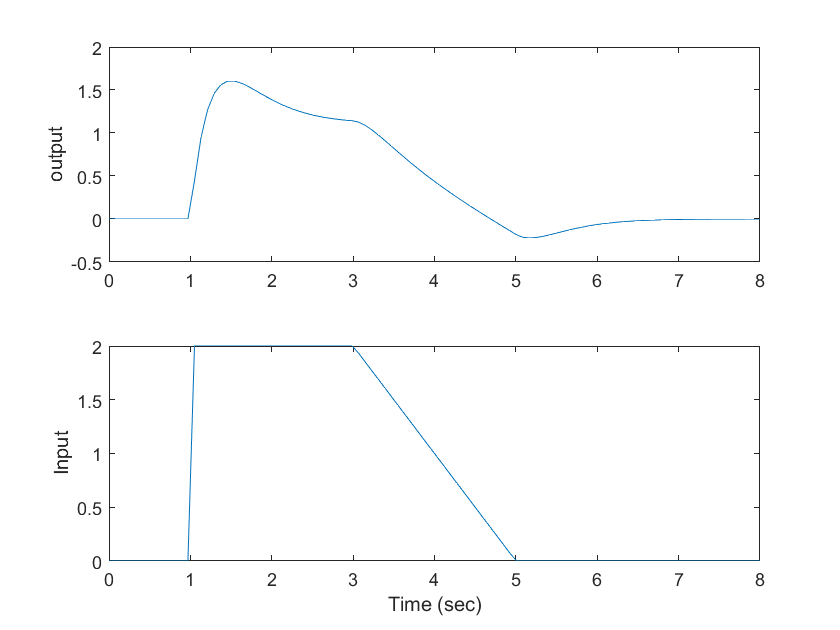


figure()
subplot(2,1,1)
plot(tm, ys)
ylabel('output')
subplot(2,1,2)
plot(tm, us)
ylabel('Input')
xlabel('Time (sec)')

The advantage of an symbolic (analytic) solution is that it is highly accurate and does not rely on numerical methods to approximate the solution. Also, the solution is in a compact form that can be used for further analysis. Symbolic solutions are limited to cases where the input function and system transfer function can be expressed in Laplace form. This may not be the case for inputs that come from data sources where there the input function has random variation. A symbolic solution with Laplace transforms is also not possible for systems that are nonlinear or complex while numeric solvers can handle many thousands or millions of equations with nonlinear relationships. The disadvantage of a numeric solution is that it is an approximation of the true solution with possible inaccuracies. Another disadvantage is that solvers may fail to converge although this is not typical on problems with an analytic solution.